clear all; close all;
type = 'real';
load('/mnt/40086D4C086D41D0/Reverb_data/coch.mat');
freqs = coch(1).params.f;  
pen_list(1,:) = 'P02';
pen_list(2,:) = 'P03';
pen_list(3,:) = 'P05';
pen_list(4,:) = 'P08';
num_pen = size(pen_list,1);
for pen_no = 1:num_pen
    dir_name = '/home/alex/Desktop/Kernels/Ronnie/';
    pen = pen_list(pen_no,:);
    switch type
        case 'real'
            full_name = [dir_name,pen,'/data/sep_kernel_adjbeta'];
            load(full_name);
            num_clusters = numel(sep_kernel);
            for clust = 1:num_clusters
                params(pen_no).beta_small(clust) = sep_kernel(clust).dexp_reverb1.beta;
                params(pen_no).beta_big(clust) = sep_kernel(clust).dexp_reverb2.beta;
                params(pen_no).beta_anech(clust) = sep_kernel(clust).dexp_anech.beta;
                anech_kh = sep_kernel(clust).anech_k_h.k_h;
                params(pen_no).anech_kh(clust,:) = anech_kh;
                params(pen_no).ie_anech(clust) = sum(abs(min(anech_kh,0)))./sum(max(anech_kh,0));
                reverb1_kh = sep_kernel(clust).reverb1_k_h.k_h;
                params(pen_no).reverb1_kh(clust,:) = reverb1_kh;
                params(pen_no).ie_reverb1(clust) = sum(abs(min(reverb1_kh,0)))./sum(max(reverb1_kh,0));
                reverb2_kh = sep_kernel(clust).reverb2_k_h.k_h;
                params(pen_no).reverb2_kh(clust,:) = reverb2_kh;
                params(pen_no).ie_reverb2(clust) = sum(abs(min(reverb2_kh,0)))./sum(max(reverb2_kh,0));
                params(pen_no).NPSP(clust) = sep_kernel(clust).NPSP;
                params(pen_no).k_f(clust) = sep_kernel(clust).full_kernel.k_f; 
                [~,ix] = max(sep_kernel(clust).full_kernel.k_f);
                params(pen_no).bf(clust) = freqs(ix);
            end
        case 'model'
            full_name = [dir_name,pen,'/data/model_adjbeta'];
            load(full_name);
            num_clusters = numel(model_kernel);
            for clust = 1:num_clusters
                params(pen_no).beta_small(clust) = model_kernel(clust).dexp_reverb1.beta;
                params(pen_no).beta_big(clust) = model_kernel(clust).dexp_reverb2.beta;
                params(pen_no).beta_anech(clust) = model_kernel(clust).dexp_anech.beta;
                anech_kh = model_kernel(clust).k_h_model_anech.k_h;
                params(pen_no).anech_kh(clust,:) = anech_kh;
                params(pen_no).ie_anech(clust) = sum(abs(min(anech_kh,0)))./sum(max(anech_kh,0));
                reverb1_kh = model_kernel(clust).k_h_model_reverb1.k_h;
                params(pen_no).reverb1_kh(clust,:) = reverb1_kh;
                params(pen_no).ie_reverb1(clust) = sum(abs(min(reverb1_kh,0)))./sum(max(reverb1_kh,0));
                reverb2_kh = model_kernel(clust).k_h_model_reverb2.k_h;
                params(pen_no).reverb2_kh(clust,:) = reverb2_kh;
                params(pen_no).ie_reverb2(clust) = sum(abs(min(reverb2_kh,0)))./sum(max(reverb2_kh,0));
                params(pen_no).NPSP(clust) = model_kernel(clust).NPSP;
                params(pen_no).k_f(clust) = model_kernel(clust).full_kernel_model.k_f;
                [~,params(pen_no).bf(clust)] = max(model_kernel(clust).full_kernel_model.k_f);
                params(pen_no).bf(clust) = freqs(ix);
            end
    end
    params(pen_no).ratio_big_small = params(pen_no).beta_big./params(pen_no).beta_small;
    params(pen_no).pen_name = pen;
end

Plot the time constants separately

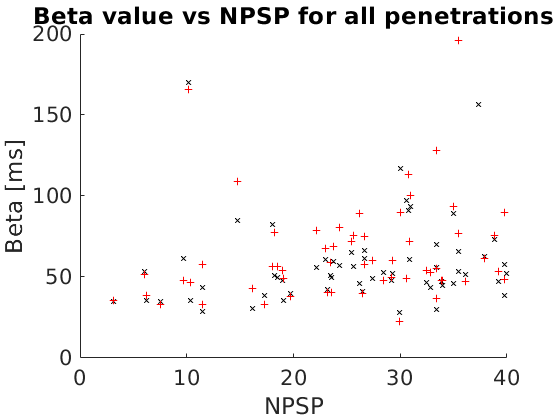

sz = 5;
color = ['b','c','m','g'];
figure;
for pen = 1:num_pen
%     plot_color = 'k';
%     plot(params(pen).NPSP,params(pen).beta_anech,['b','o'],'MarkerSize',sz);
    hold on;
    plot(params(pen).NPSP,params(pen).beta_small,['k','x'],'MarkerSize',sz);
    plot(params(pen).NPSP,params(pen).beta_big,['r','+'],'MarkerSize',sz);
    ylim([0 200]);
    xlim([0 40]);
end
xlabel('NPSP');
ylabel('Beta [ms]');
title('Beta value vs NPSP for all penetrations');
hold off;

Plot the ratio of beta big vs beta small

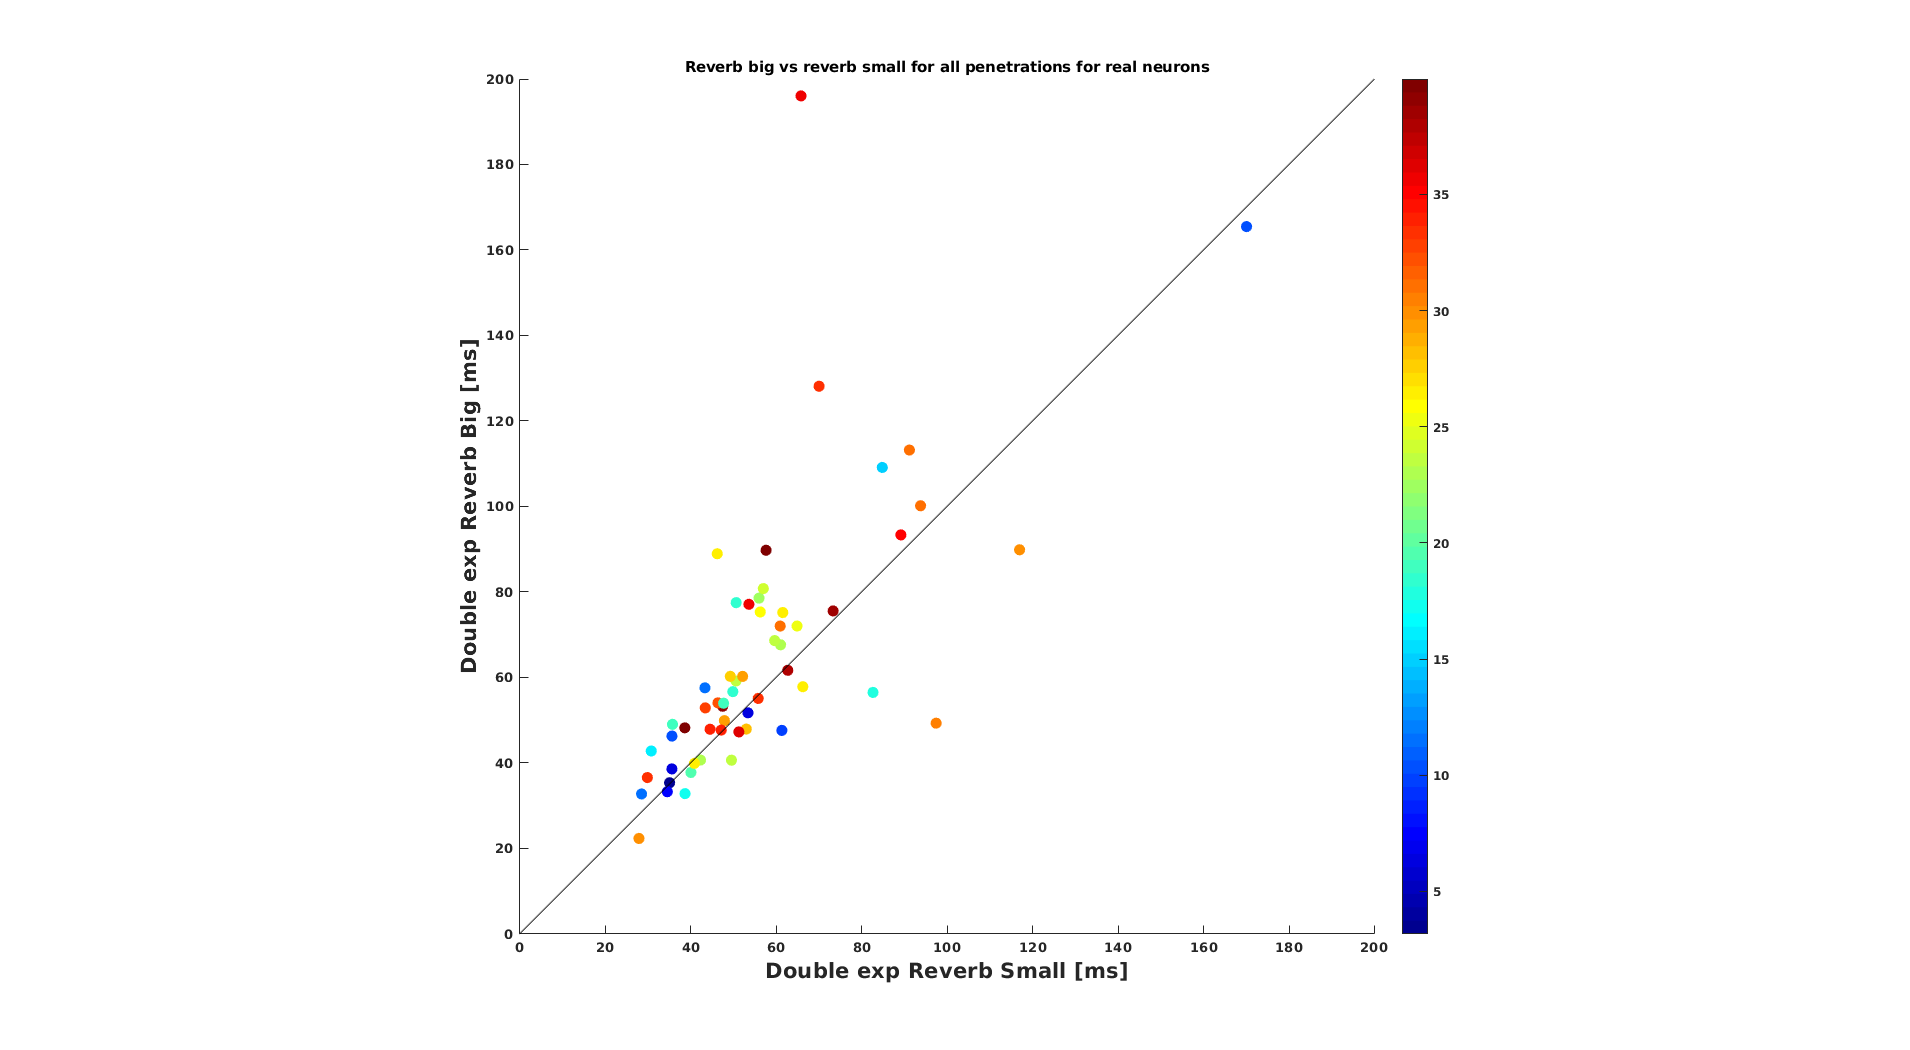

big_beta = reach(params,'beta_big');
small_beta = reach(params,'beta_small');
NPSP = reach(params,'NPSP');
lim_val = 200;
c = NPSP;
sz = 70;
figure('units','normalized','outerposition',[0 0 1 1]);
scatter(small_beta,big_beta,sz,c,'filled');
set(gca,'FontName','Arial','FontSize',10,'FontWeight','Bold');
xlabel('Double exp Reverb Small [ms]','FontSize',16,'FontWeight','bold');
ylabel('Double exp Reverb Big [ms]','FontSize',16,'FontWeight','bold');
title(['Reverb big vs reverb small for all penetrations for ',type,' neurons']);
colormap('jet');
colorbar;
axis equal;
l = [0 lim_val];
xlim(l);
ylim(l);
hline = refline(1,0);
hline.Color = 'k';
save_name = [dir_name,'/Summary_data/',type,'_neurons_all_data_Dexp.png'];
export_fig(save_name);

Plot a histrogram for the distribution of differences big-small beta

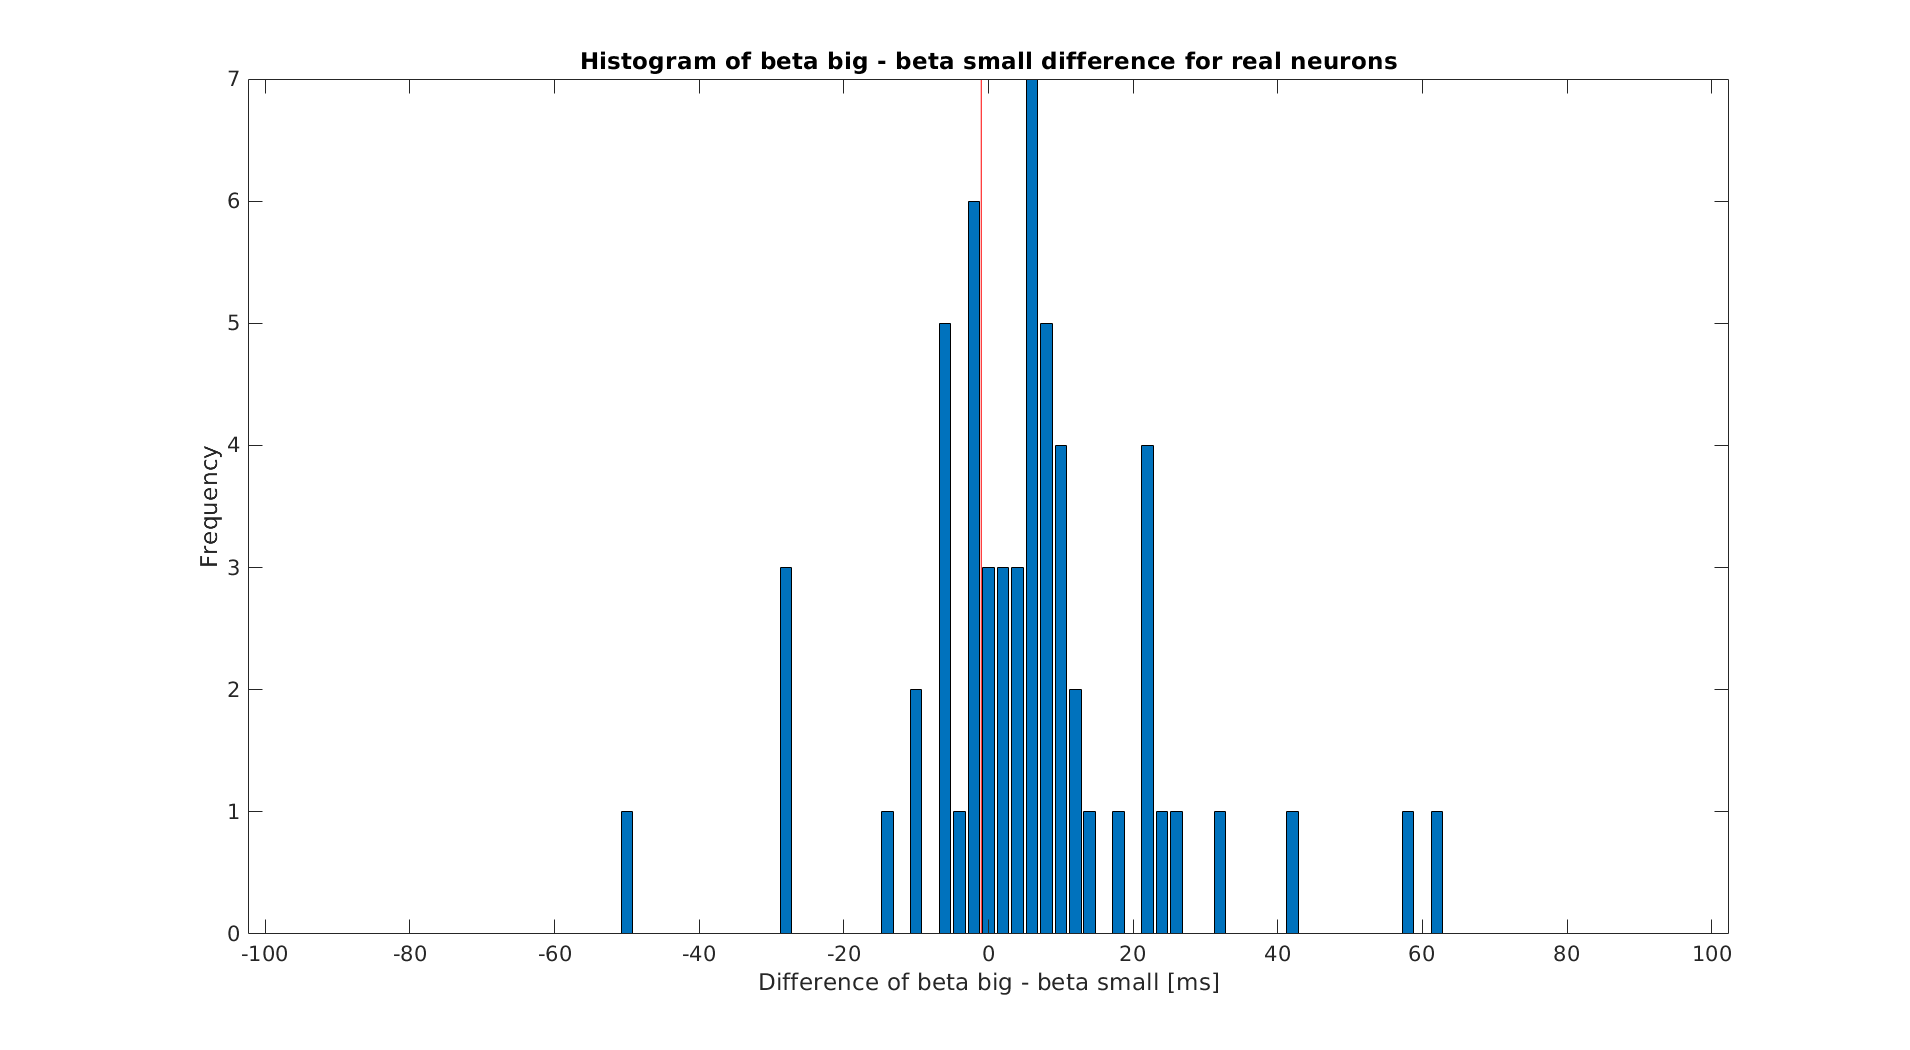

beta_diff = big_beta - small_beta;
save([dir_name,'/Summary_data/',type,'_diff'],'beta_diff');
bin_width_ms = 2;
spacing = 10;
edge_ms = 100;
edges = [-edge_ms:bin_width_ms:edge_ms];
hist_diff = histc(beta_diff,edges);
figure('units','normalized','outerposition',[0 0 1 1]);
bar(hist_diff);
for jj = 1:numel(edges)
    x_labels{jj} = num2str(edges(jj),'%.0f');
end
vline(numel(edges)/2,'r');
xticks([1:spacing:numel(edges)]);
xticklabels(x_labels([1:spacing:numel(edges)]));
xlabel('Difference of beta big - beta small [ms]');
ylabel('Frequency','FontSize',16);
title(['Histogram of beta big - beta small difference for ',type,' neurons']);
set(0,'defaultAxesFontSize',16);
save_name = [dir_name,'/Summary_data/',type,'_neurons_all_data_histogram_diff.png'];
export_fig(save_name);

Calculate the I/E ratio for all neurons

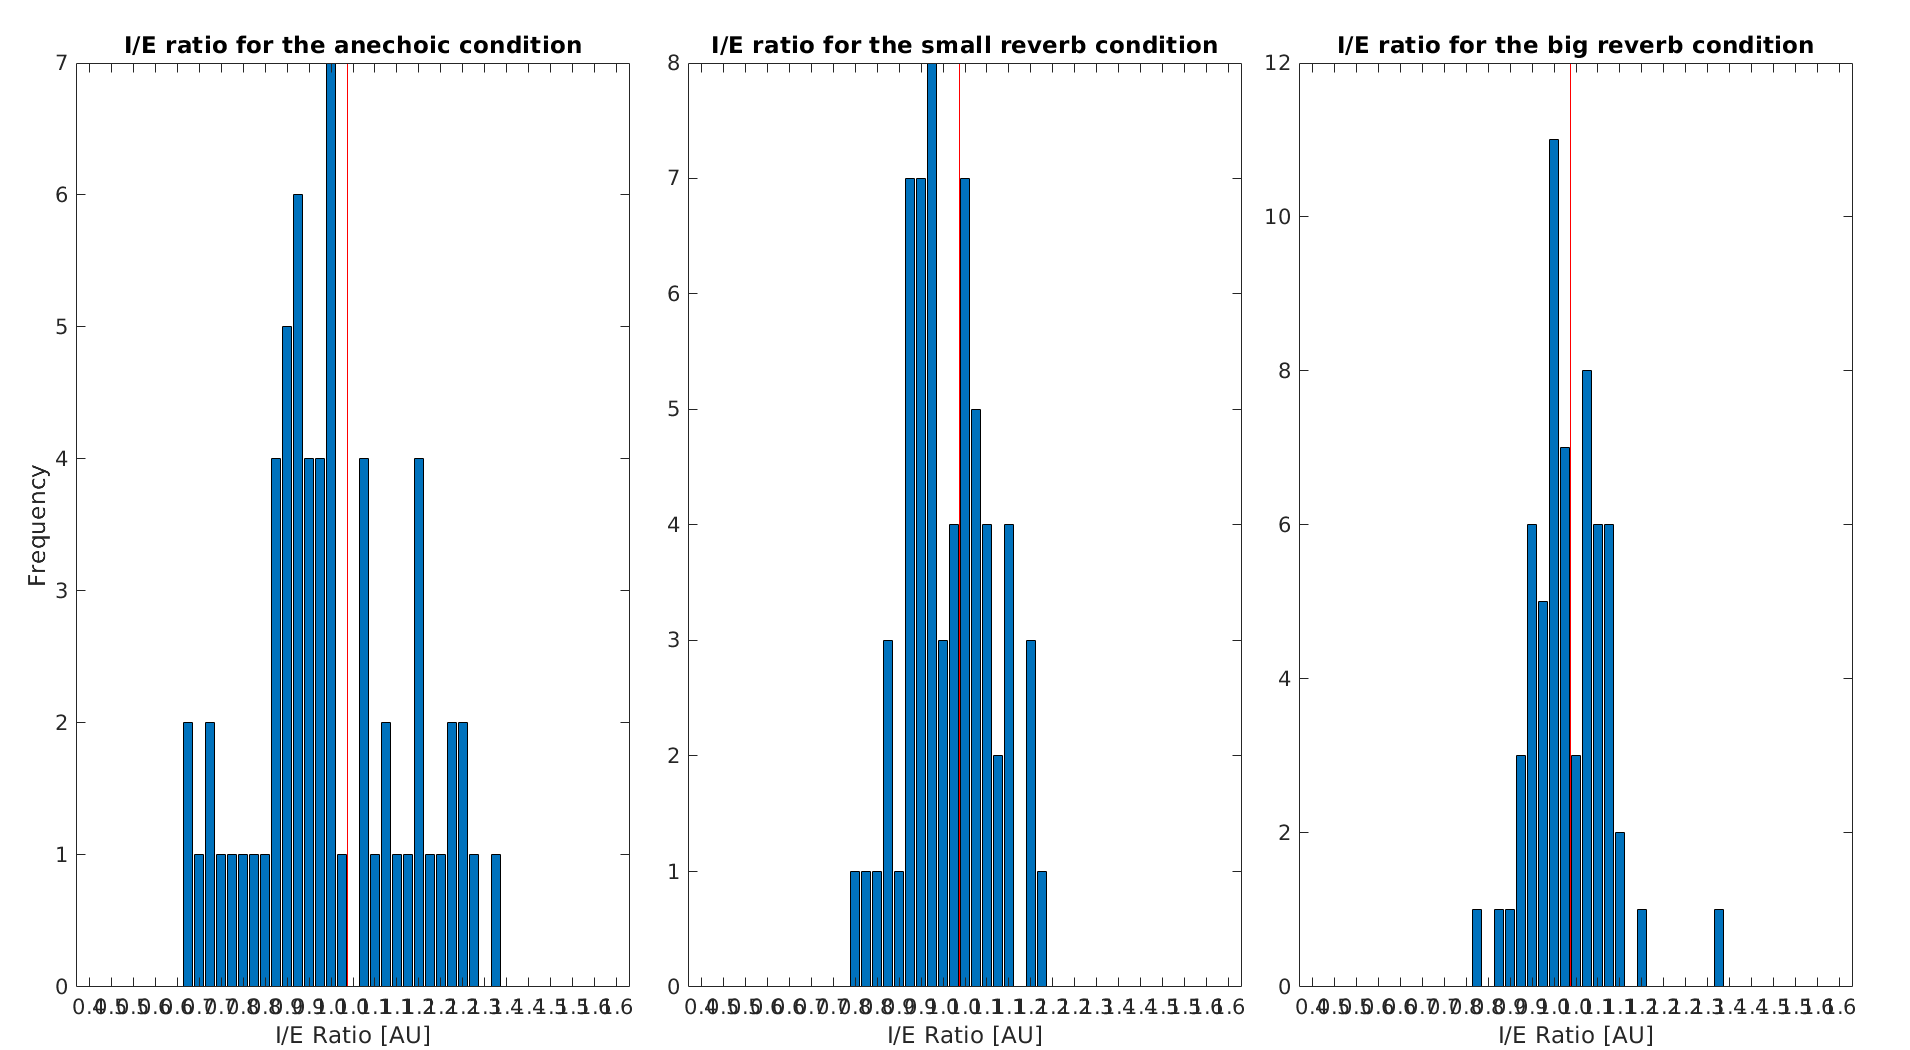

ie_anech = reach(params,'ie_anech');
ie_reverb1 = reach(params,'ie_reverb1');
ie_reverb2 = reach(params,'ie_reverb2');
sz = 10;
edge_ie = 1.6;
spacing = 2;
bin_width = 0.025;
edges = [0.4:bin_width:1.6];
for jj = 1:numel(edges)
    x_labels{jj} = num2str(edges(jj),'%.1f');
end
figure('units','normalized','outerposition',[0 0 1 1]);
row = 1;
col = 3;
per = 0.03;
edgel = 0.04; edger = per; edgeh = 0.06; edgeb = 0.06; space_h = per; space_v = per;
[pos]=subplot_pos(row,col,edgel,edger,edgeh,edgeb,space_h,space_v);

subplot('position',pos{1});
hist_anech_ie = histc(ie_anech,edges);
bar(hist_anech_ie);
vline(numel(edges)/2,'r');
xticks([1:spacing:numel(edges)]);
xticklabels(x_labels([1:spacing:numel(edges)]));
title('I/E ratio for the anechoic condition');
ylabel('Frequency','FontSize',sz);
xlabel('I/E Ratio [AU]','FontSize',sz);

subplot('position',pos{2});
hist_reverb1_ie = histc(ie_reverb1,edges);
bar(hist_reverb1_ie);
vline(numel(edges)/2,'r');
xticks([1:spacing:numel(edges)]);
xticklabels(x_labels([1:spacing:numel(edges)]));
title('I/E ratio for the small reverb condition');
xlabel('I/E Ratio [AU]','FontSize',sz);

subplot('position',pos{3});
hist_reverb2_ie = histc(ie_reverb2,edges);
bar(hist_reverb2_ie);
vline(numel(edges)/2,'r');
xticks([1:spacing:numel(edges)]);
xticklabels(x_labels([1:spacing:numel(edges)]));
title('I/E ratio for the big reverb condition');
xlabel('I/E Ratio [AU]','FontSize',sz);

save_name = [dir_name,'/Summary_data/',type,'_neurons_all_data_histogram_ie_cond.png'];
export_fig(save_name);

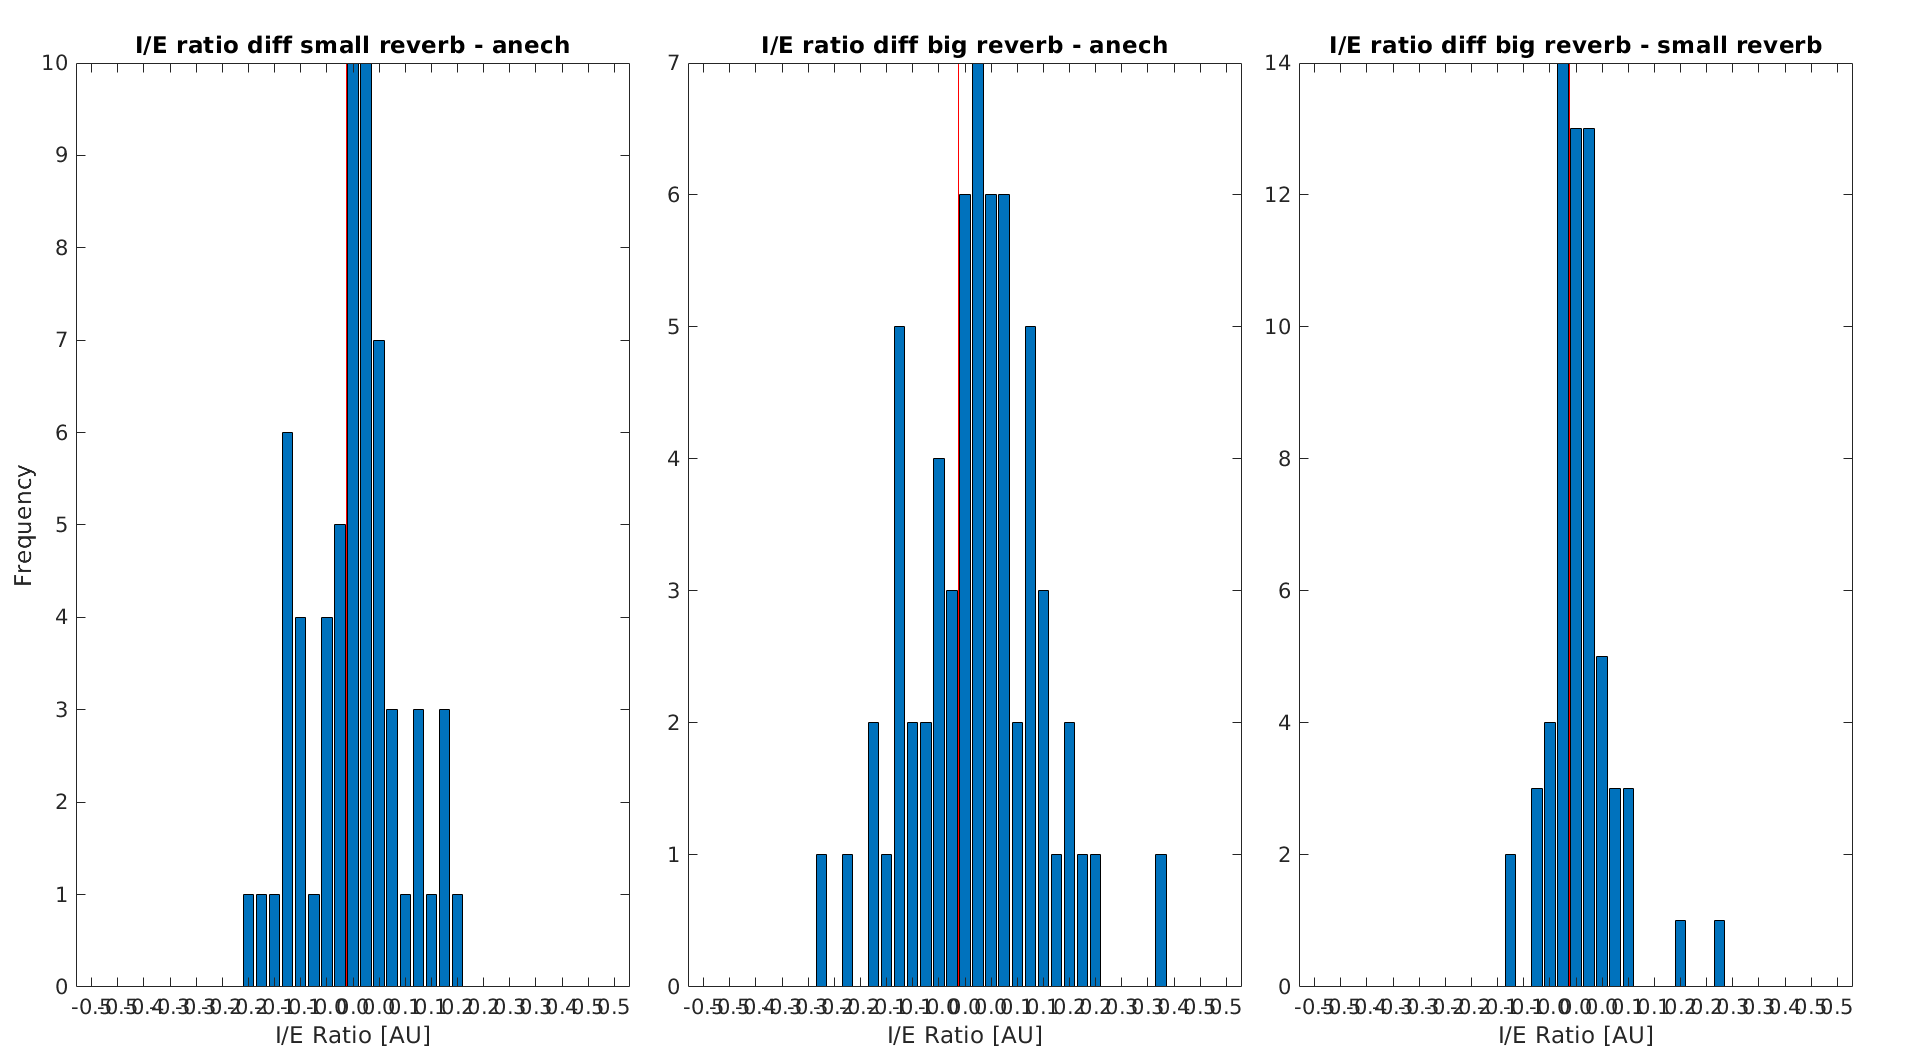


edges = [-0.5:bin_width:0.5];
figure('units','normalized','outerposition',[0 0 1 1]);

for jj = 1:numel(edges)
    x_labels{jj} = num2str(edges(jj),'%.1f');
end

subplot('position',pos{1});
hist_diff_r1_anech_ie = histc(ie_reverb1 - ie_anech,edges);
bar(hist_diff_r1_anech_ie);
vline(numel(edges)/2,'r');
xticks([1:spacing:numel(edges)]);
xticklabels(x_labels([1:spacing:numel(edges)]));
title('I/E ratio diff small reverb - anech');
ylabel('Frequency','FontSize',sz);
xlabel('I/E Ratio [AU]','FontSize',sz);

subplot('position',pos{2});
hist_diff_r2_anech_ie = histc(ie_reverb2 - ie_anech,edges);
bar(hist_diff_r2_anech_ie);
vline(numel(edges)/2,'r');
xticks([1:spacing:numel(edges)]);
xticklabels(x_labels([1:spacing:numel(edges)]));
title('I/E ratio diff big reverb - anech');
xlabel('I/E Ratio [AU]','FontSize',sz);

subplot('position',pos{3});
hist_diff_r2_anech_ie = histc(ie_reverb2 - ie_reverb1,edges);
bar(hist_diff_r2_anech_ie);
vline(numel(edges)/2,'r');
xticks([1:spacing:numel(edges)]);
xticklabels(x_labels([1:spacing:numel(edges)]));
title('I/E ratio diff big reverb - small reverb');
xlabel('I/E Ratio [AU]','FontSize',sz);

save_name = [dir_name,'/Summary_data/',type,'_neurons_all_data_histogram_ie_cond_diff.png'];
export_fig(save_name);

Plot the ratio of big/small reverb betas

figure;
sz = 15;
hold on;
for pen = 1:num_pen
    plot_color = color(pen);
    plot(params(pen).NPSP,params(pen).ratio_big_small,[plot_color,'.'],'MarkerSize',sz);
end
xlabel('NPSP');
ylabel('Beta big/beta small Ratio');
title('Beta big/beta small Ratio vs NPSP for all penetrations');
legend('P02','P03','P05','P08');

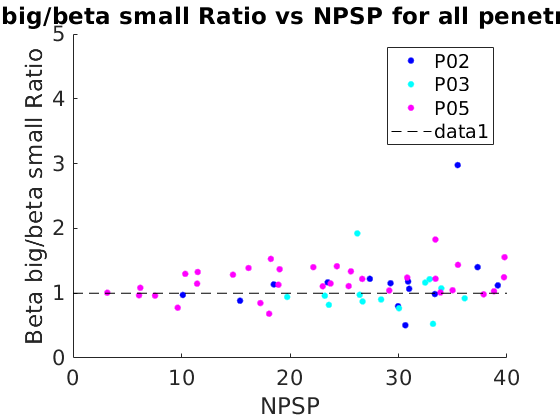

plot([0:40],ones(41,1),'k--');
ylim([0 5]);
hold off;

NPSP_small = NPSP(NPSP<20);
ratio = reach(params,'ratio_big_small');

s = signtest(big_beta,small_beta);
s_median = median(big_beta - small_beta);
s_mean = mean(big_beta - small_beta);
s_small = signtest(big_beta(NPSP<20),small_beta(NPSP<20)); 
s_median_small = median(big_beta(NPSP<20) - small_beta(NPSP<20));
s_mean_small = mean(big_beta(NPSP<20) - small_beta(NPSP<20));

Perform statistical test on the two distriutions of real and model betas

real_diff = load([dir_name,'/Summary_data/real_diff']);
model_diff = load([dir_name,'/Summary_data/model_diff']);
p_diff_real_model = signtest(real_diff.beta_diff,model_diff.beta_diff); 